## Vectors

a = [1 2 3 4]

a =      1     2     3     4


t = 0:2:20 % 0到20 以2为增量均匀分布

t =      0     2     4     6     8    10    12    14    16    18    20


b = a + 2 % 向量相加

b =      3     4     5     6


c = a + b % 向量相加

c =      4     6     8    10


## Functions

% sin, cos, log, exp, sqrt
% pi, i, j
sin(pi/4)

ans = 0.7071

exp(-1)

ans = 0.3679

a = 1+2i

a = 1.0000 + 2.0000i

b = 1-2j

b = 1.0000 - 2.0000i

c = a + b

c = 2

## Plotting

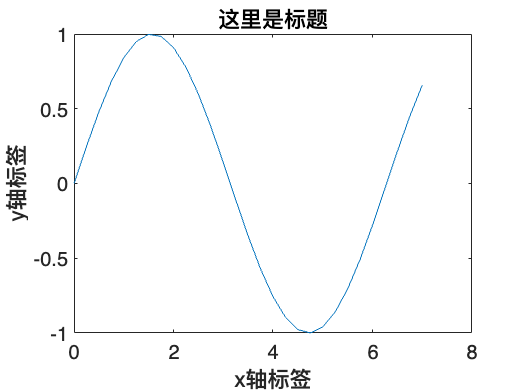

% plot(title, xlabel, ylabel) 
t = 0:0.25:7;
y = sin(t);

plot(t,y);
title('这里是标题');
xlabel('x轴标签');
ylabel('y轴标签');

## Polynomials

% 按照降序创建多项式
x = [4 3 -15 -2 9];
y = [2 0 0 0 3];
z = polyval(y,-1) % 求解s=-1时多项式y的值

z = 5

roots([1 5 6]) % 求解给定多项式的根

ans =    -3.0000
   -2.0000


m = conv(x,y) % 多项式乘法

z =      8     6   -30    -4    30     9   -45    -6    27


[xx , R] = deconv(x,y) % 多项式除法

xx = 2

R =      0     3   -15    -2     3


## Poltnomials  Using S

s = tf('s');
sys = s^4+3*s^3-15*s^2-2*s+9

sys =
 
  s^4 + 3 s^3 - 15 s^2 - 2 s + 9
 
连续时间传递函数。
模型属性


zero(sys) % 利用zero查找带s的多项式根

ans =    -5.5745
    2.5836
   -0.7951
    0.7860


x = s + 2;
z = x * sys %多项式直接相乘

z =
 
  s^5 + 5 s^4 - 9 s^3 - 32 s^2 + 5 s + 18
 
连续时间传递函数。
模型属性


## Matrices

A = [1 2 3 4;5 6 7 8;9 10 11 12]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12


B = [12 11 10
      9 8 7 
      6 5 4
      3 2 1 ]

B =     12    11    10
     9     8     7
     6     5     4
     3     2     1


C = A' % 求矩阵转置

C =      1     5     9
     2     6    10
     3     7    11
     4     8    12


D1 = A * B

D1 =     60    50    40
   180   154   128
   300   258   216


D2 = B * A

D2 =    157   190   223   256
   112   136   160   184
    67    82    97   112
    22    28    34    40


D3 = B .* C

D3 =     12    55    90
    18    48    70
    18    35    44
    12    16    12


E1 = D2^3

E1 =     28369780    34609720    40849660    47089600
    20299840    24764800    29229760    33694720
    12229900    14919880    17609860    20299840
     4159960     5074960     5989960     6904960


E2 = D3.^3

E2 =         1728      166375      729000
        5832      110592      343000
        5832       42875       85184
        1728        4096        1728


F = [1 1 1;2 7 8;3 5 7]

F =      1     1     1
     2     7     8
     3     5     7


X = inv(F) % 求方阵的逆

X =     1.1250   -0.2500    0.1250
    1.2500    0.5000   -0.7500
   -1.3750   -0.2500    0.6250


eig(E1) % 求方阵的特征值

ans = 1.0e+07 *

    7.7649
    0.0000
   -0.0000
   -0.0000


p = poly(E1) % 创建特征多项式

p = 1.0e+09 *

    0.0000   -0.0776    2.9860    0.0000    0.0000


roots(p) % 求特征多项式的根 = 矩阵的特征值

ans = 1.0e+07 *

    7.7649
    0.0000
   -0.0000
   -0.0000


## 使用技巧(更改全部的图片属性)

figure(2)
s = tf('s');
sys = s^3+s^2+2*s+1

sys =
 
  s^3 + s^2 + 2 s + 1
 
连续时间传递函数。
模型属性


den = 2*s+1

den =
 
  2 s + 1
 
连续时间传递函数。
模型属性


G = (s-5)/den

G =
 
   s - 5
  -------
  2 s + 1
 
连续时间传递函数。
模型属性


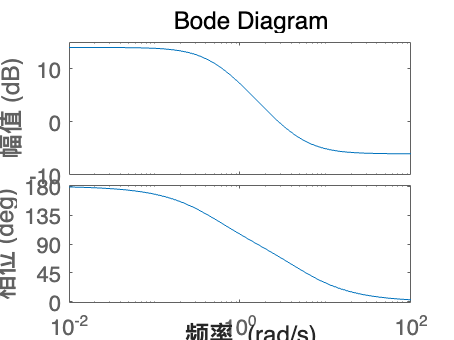

bode(G)

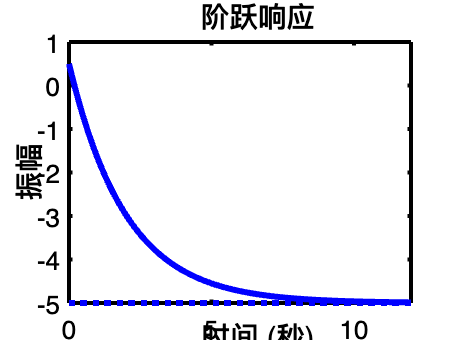

step(G)
% Set title, axes labels, and legend font size
set(findall(gcf,'Type','text'),'FontSize',13)
% Set data line width and color
set(findall(gcf,'Type','line'),'LineWidth',3,'Color','blue')
% Set axes tick label font size, color, and line width
set(findall(gcf,'Type','axes'),'FontSize',13,'LineWidth',2,'XColor','black','YColor','black')